# Fastest Descent

## Analytical solution

Ref: [https://en.wikipedia.org/wiki/Brachistochrone_curve](https://en.wikipedia.org/wiki/Brachistochrone_curve)


$$\begin{array}{l}
x=r\left(\;\;\;\varphi -\;\sin \varphi \right)\\
y=r\left(-1+\cos \varphi \right)
\end{array}$$


initial condition is $\left(x,y\right)=\left(0,0\right)$ i.e. $\varphi =0$

clear 

r = 1;
phi = linspace(0,2*pi,200+1);
x_exact = r*(phi-sin(phi))';
y_exact = r*( -1+cos(phi))';

## Set up Multibody Simulation

% stay inside the spline by a tolerance
x_eps = 1e-5;  % stay inside x < pi-x_eps 
y_eps = 1e-5;  % start at y = - y_eps;

% initial guess
N = 4;
% x_spline = linspace(0,pi,N+1)';
% y_spline = -2/pi*x_spline;

x_spline = ( (1-cos([0:N]/N*pi/2))*pi )';
y_spline = -2/pi*x_spline;

figure(100); clf;
hold on
plot(x_exact ,y_exact )
plot(x_spline,y_spline,'.-')
ax = gca;
ax.XTick = [0:4]/4*pi;
ax.XTickLabel = ["0","\pi/4","\pi/2","3\pi/4","\pi"];
ax.XLim = [0,pi];
ax.YTick = [-2:0.5:0];

open_system("model_spline.slx");

return

## Optimization Script

Using function generated by Simulink Design Optimization GUI

N = 6;
x_spline = ( (1-cos([0:N]/N*pi/2))*pi )';
y_spline = -2/pi*x_spline;

[Optimized_y_spline, Info] = responseOptimization_model_spline();


 Optimization started 05-Apr-2022 12:15:06

                               max                     First-order 
 Iter F-count        f(x)   constraint    Step-size    optimality
    0     11      1.18924            0
    1     22      1.11908            0        0.312        0.114
    2     33      1.05778            0        0.487       0.0605
    3     44      1.02781            0        0.482        0.035
    4     55      1.01616            0        0.425       0.0292
    5     66      1.01322            0        0.302       0.0339
    6     77      1.01231            0        0.137       0.0164
    7     87      1.01062            0        0.249       0.0149
    8     97      1.00952            0        0.201       0.0154
    9    107      1.00867            0        0.191      0.00958
   10    117      1.00837            0       0.0648       0.0122
   11    127      1.00772            0        0.101       0.0148
   12    137      1.00695            0        0.169       0.0173
  

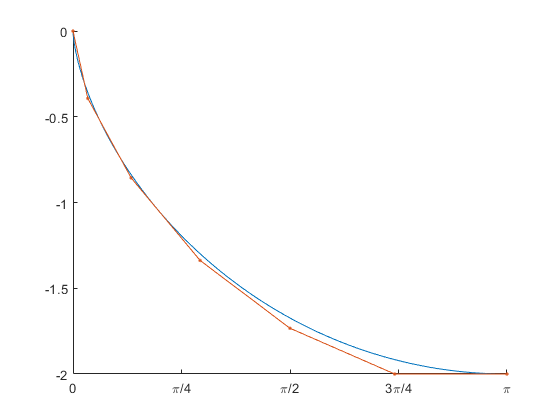


y_spline = Optimized_y_spline.Value;

figure(101); clf;
hold on
plot(x_exact ,y_exact )
plot(x_spline,y_spline,'.-')
ax = gca;
ax.XTick = [0:4]/4*pi;
ax.XTickLabel = ["0","\pi/4","\pi/2","3\pi/4","\pi"];
ax.XLim = [0,pi];
ax.YTick = [-2:0.5:0];

*Copyright 2021 The MathWorks, Inc.*